Experiment One

Step 1

SNR_of = 10*log10(sum(y(1:T,1).^2)./sum(noise(:,1).^2));  %計算左聲道原本的的訊雜比

Unrecognized function or variable 'T'.

SNR_or = 10*log10(sum(y(1:T,2).^2)./sum(noise(:,2).^2));  %計算右聲道原本的的訊雜比

Step 2

SNR = 5;
[output, fs] = audio_SNR('1.wav', 'horn.wav', SNR);
% sound(output, fs);
audiowrite('1_horn.wav', output, fs);

Experiment Two

Step 3

[signal,fs] = audioread('1.wav'); 
sound(signal*5,fs);

Step 4

s = 0.5;
output1 = WienerScalart96(output,fs,s);
sound(output1,fs);
audiowrite('1_horn_reduced.wav', output1, fs);

Step 5

% Load audio files
clean_speech = audioread('1.wav'); % Clean speech
noisy_speech = audioread('1_horn.wav'); % Noisy speech
denoised_speech = audioread('1_horn_reduced.wav'); % Noise-reduced speech

clean_speech = clean_speech(:);
noisy_speech = noisy_speech(:);
denoised_speech = denoised_speech(:);

% Ensure signals are of the same length
min_len = min([length(clean_speech), length(noisy_speech), length(denoised_speech)]);
clean_speech = clean_speech(1:min_len);
noisy_speech = noisy_speech(1:min_len);
denoised_speech = denoised_speech(1:min_len);

% Segment length for SSNR calculation
frame_length = 256; % Typically 20-30 ms at 16 kHz
overlap = frame_length / 2; % 50% overlap

% Function to calculate SSNR
function ssnr = calculate_ssnr(clean, noisy, frame_len, overlap)
    step = frame_len - overlap; % Step size for overlapping frames
    num_frames = floor((length(clean) - frame_len) / step) + 1; % Number of frames
    ssnr_values = zeros(1, num_frames); % Initialize SSNR array

    for i = 1:num_frames
        start_idx = (i - 1) * step + 1; % Start index of the frame
        end_idx = start_idx + frame_len - 1; % End index of the frame

        clean_frame = clean(start_idx:end_idx); % Extract clean frame
        noisy_frame = noisy(start_idx:end_idx); % Extract noisy frame

        % Calculate signal and noise power (ensure scalar values)
        signal_power = sum(clean_frame .^ 2); % Sum of squared signal values
        noise_power = sum((clean_frame - noisy_frame) .^ 2); % Sum of squared noise values

        % Avoid division by zero and handle edge cases
        if noise_power > 0
            ssnr_values(i) = 10 * log10(signal_power / noise_power); % SSNR for this frame
        else
            ssnr_values(i) = 0; % Assign 0 SSNR if noise_power is 0
        end
    end

    ssnr = mean(ssnr_values); % Average SSNR over all frames
end


% Calculate SSNRs
ssnr_noisy = calculate_ssnr(clean_speech, noisy_speech, frame_length, overlap);
ssnr_denoised = calculate_ssnr(clean_speech, denoised_speech, frame_length, overlap);

% Calculate SSNRI
ssnri = ssnr_denoised - ssnr_noisy;

% Display results
fprintf('SSNR (Noisy): %.2f dB\n', ssnr_noisy);
fprintf('SSNR (Denoised): %.2f dB\n', ssnr_denoised);
fprintf('SSNRI: %.2f dB\n', ssnri);


Experiment Three

clc; clear;

[input, fs] = audioread('1.wav');
mic = [1, 2, 2];
nn = 3;
src = [2, 3, 1];
rm = [5, 5, 4];
a = 1;
h = rir(fs, mic, nn, a, rm, src);
d = filter(h, 1, input);
sound(d, fs);
audiowrite('echoaudio.wav', d, fs);

Experiment Four

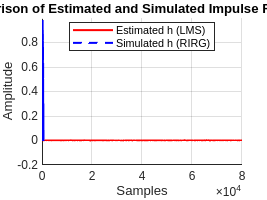

input = randn(1, 8e4);
fs = 10000;
%% Parameters
N = 291; % Filter length
mu = 0.0006; % Step-size parameter
w0 = zeros(N,1); % Initial weights for LMS filter
p = 1; % Placeholder if needed
n = length(input); % Length of the input signal
Amse_lms = zeros(n,1); % Initialize MSE storage

%% LMS Filter Call
% Call the LMS function to estimate h_hat
[e, w] = full_lms(input, d, N, w0, mu); % w contains the estimated filter coefficients

% The estimated impulse response is the final set of weights
h_hat = w(:, end);

%% Simulated Impulse Response (h from RIRG)
% Ensure you have a simulated impulse response 'h' from your RIRG generator
% Example: h = RIRG(...); % Use the RIRG function or your predefined impulse response

%% Plotting Impulse Responses
figure;
hold on;

% Plot estimated impulse response (h_hat)
plot(h_hat, 'r', 'LineWidth', 1.5, 'DisplayName', 'Estimated h (LMS)');

% Plot simulated impulse response (h)
plot(h, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Simulated h (RIRG)');

% Add labels and legend
xlabel('Samples');
ylabel('Amplitude');
title('Comparison of Estimated and Simulated Impulse Responses');
legend('Location', 'best');
grid on;

hold off;

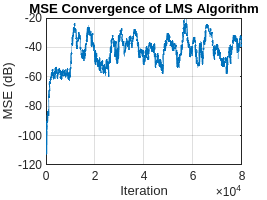


%% Calculate MSE
Amse_lms(:,1) = Amse_lms(:,1) + e(:,1).^2; % Amse_lms = msesim(lms,input',d',1);
L_ave = 80;                         
b_ave = [1, zeros(1, L_ave-1), -1];    
a_ave = [1, -1] * L_ave;

mse_lms = filter(b_ave, a_ave, Amse_lms); % Smooth MSE
mse_lms = 10 * log10(mse_lms); % Convert to dB

% Plot MSE
figure;
plot(mse_lms, 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('MSE (dB)');
title('MSE Convergence of LMS Algorithm');
grid on;

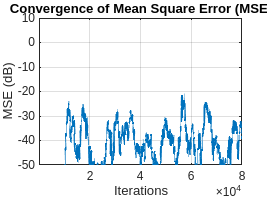


%% Observing MSE Convergence

% Plot the MSE
figure;
plot(mse_lms, 'LineWidth', 1.5);

% Add labels, title, and grid
xlabel('Iterations');
ylabel('MSE (dB)');
title('Convergence of Mean Square Error (MSE)');
grid on;

% Highlight key observations
xlim([1, length(mse_lms)]); % Adjust x-axis to fit the data length
ylim([-50, 10]); % Set appropriate y-axis limits for decibel values

Experiment Five

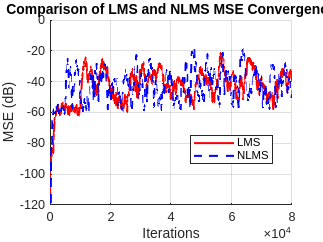

function [e, w] = full_nlms(input, d, N, w0, mu, alpha)
    % Ensure input is a column vector
    input = input(:); % Force column vector

    % Initialize variables
    w = zeros(N, length(input)); % Weight matrix
    e = zeros(length(input), 1); % Error vector
    w(:, 1) = w0; % Initial weights
    
    % Iterative NLMS algorithm
    for n = N:length(input)
        % Input vector x(n)
        x_n = input(n:-1:n-N+1); % Extract N most recent samples
        
        % Ensure x_n is a column vector
        x_n = x_n(:); 
        
        % Filter output (dot product of w and x_n)
        y_n = w(:, n)' * x_n;
        
        % Error calculation
        e(n) = d(n) - y_n;
        
        % NLMS weight update
        normalization = alpha + x_n' * x_n; % Normalized factor
        w(:, n+1) = w(:, n) + (mu / normalization) * x_n * e(n); % Update rule
    end
    
    % Return error and weights
    w = w(:, 1:end-1); % Remove the last unused weight column
end


input = input(:); % Force column vector

% Call LMS
[e_lms, w_lms] = full_lms(input, d, N, w0, mu);

% Call NLMS
alpha = 1e-10; % Small constant
[e_nlms, w_nlms] = full_nlms(input, d, N, w0, mu, alpha);

% Calculate MSE for LMS
Amse_lms = e_lms.^2;
mse_lms = 10 * log10(filter(b_ave, a_ave, Amse_lms));

% Calculate MSE for NLMS
Amse_nlms = e_nlms.^2;
mse_nlms = 10 * log10(filter(b_ave, a_ave, Amse_nlms));

% Plot Comparison
figure;
hold on;
plot(mse_lms, 'r', 'LineWidth', 1.5, 'DisplayName', 'LMS');
plot(mse_nlms, 'b--', 'LineWidth', 1.5, 'DisplayName', 'NLMS');
xlabel('Iterations');
ylabel('MSE (dB)');
title('Comparison of LMS and NLMS MSE Convergence');
legend('Location', 'best');
grid on;
hold off;

Question One

function noisySpeech = add_noise(cleanSpeech, noise, snrTarget)
    % Calculate signal power
    signalPower = mean(cleanSpeech.^2);
    
    % Scale noise to achieve target SNR
    noisePower = mean(noise.^2);
    scale = sqrt(signalPower / (10^(snrTarget / 10) * noisePower));
    scaledNoise = scale * noise;
    
    % Add scaled noise to the clean speech
    noisySpeech = cleanSpeech + scaledNoise;
end

% Step 1: Load the clean speech and noise files
[cleanSpeech, fs] = audioread('2.wav'); % Read clean speech file
[noise, fs_noise] = audioread('horn.wav'); % Read horn noise file

% Ensure both signals are of the same length
len = min(length(cleanSpeech), length(noise));
cleanSpeech = cleanSpeech(1:len);
noise = noise(1:len);

% Step 2: Add noise to the clean speech at 5 dB SNR
snrTarget = 5; % Desired SNR in dB
noisySpeech = add_noise(cleanSpeech, noise, snrTarget);

% Step 3: Apply Wiener filtering (using wienerscalart96.m)
denoisedSpeech = WienerScalart96(noisySpeech, fs); % Process the noisy signal

% Step 4: Save the denoised audio to a file
audiowrite('denoised_audio.wav', denoisedSpeech, fs);

% Display a success message
disp('Denoised audio saved as denoised_audio.wav.');

Denoised audio saved as denoised_audio.wav.


%--------------------------------------------------------------------
function adjustedSignal = adjust_length(signal, targetLength)
    % Ensure the signal is mono
    if size(signal, 2) > 1
        signal = mean(signal, 2); % Convert stereo to mono by averaging channels
    end
    
    % Adjust the signal length
    if length(signal) > targetLength
        % Truncate the signal
        adjustedSignal = signal(1:targetLength);
    else
        % Pad with zeros if the signal is too short
        adjustedSignal = [signal; zeros(targetLength - length(signal), 1)];
    end
end




% Step 1: Load clean speech
[cleanSpeech, fs] = audioread('1.wav');

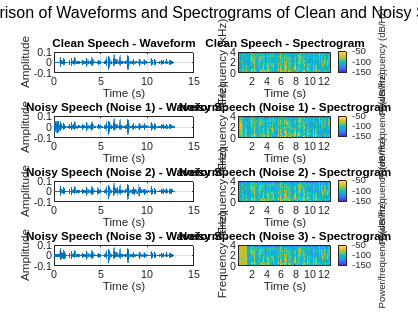


% Step 2: Load noise files
[noise1, fs1] = audioread('horn.wav'); % Noise type 1
[noise2, fs2] = audioread('mouse.wav'); % Noise type 2
[noise3, fs3] = audioread('whitenoise.wav'); % Noise type 3

% Convert clean speech to mono if necessary
if size(cleanSpeech, 2) > 1
    cleanSpeech = mean(cleanSpeech, 2); % Convert stereo to mono
end

% Convert noise signals to mono if necessary
if size(noise1, 2) > 1
    noise1 = mean(noise1, 2); % Convert stereo to mono
end
if size(noise2, 2) > 1
    noise2 = mean(noise2, 2); % Convert stereo to mono
end
if size(noise3, 2) > 1
    noise3 = mean(noise3, 2); % Convert stereo to mono
end


% Step 4: Adjust noise lengths to match clean speech length
len = length(cleanSpeech);

% Truncate or pad noise signals to match the length of the clean speech
noise1 = adjust_length(noise1, len);
noise2 = adjust_length(noise2, len);
noise3 = adjust_length(noise3, len);

% Step 5: Add noise to clean speech at 5 dB SNR
snrTarget = 5; % Desired SNR in dB
noisySpeech1 = add_noise(cleanSpeech, noise1, snrTarget);
noisySpeech2 = add_noise(cleanSpeech, noise2, snrTarget);
noisySpeech3 = add_noise(cleanSpeech, noise3, snrTarget);

% Step 6: Plot waveforms and spectrograms
figure;

% Plot clean speech
subplot(4, 2, 1);
plot((1:len)/fs, cleanSpeech);
title('Clean Speech - Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4, 2, 2);
spectrogram(cleanSpeech, 256, 250, 256, fs, 'yaxis');
title('Clean Speech - Spectrogram');

% Plot noisy speech with Noise 1
subplot(4, 2, 3);
plot((1:len)/fs, noisySpeech1);
title('Noisy Speech (Noise 1) - Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4, 2, 4);
spectrogram(noisySpeech1, 256, 250, 256, fs, 'yaxis');
title('Noisy Speech (Noise 1) - Spectrogram');

% Plot noisy speech with Noise 2
subplot(4, 2, 5);
plot((1:len)/fs, noisySpeech2);
title('Noisy Speech (Noise 2) - Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4, 2, 6);
spectrogram(noisySpeech2, 256, 250, 256, fs, 'yaxis');
title('Noisy Speech (Noise 2) - Spectrogram');

% Plot noisy speech with Noise 3
subplot(4, 2, 7);
plot((1:len)/fs, noisySpeech3);
title('Noisy Speech (Noise 3) - Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4, 2, 8);
spectrogram(noisySpeech3, 256, 250, 256, fs, 'yaxis');
title('Noisy Speech (Noise 3) - Spectrogram');

sgtitle('Comparison of Waveforms and Spectrograms of Clean and Noisy Speech');

Question Two

function noisySpeech = add_noise_Two(cleanSpeech, noise, snrTarget)
    % Ensure the noise is the same length as the clean speech
    if length(noise) > length(cleanSpeech)
        noise = noise(1:length(cleanSpeech)); % Truncate noise if it's too long
    elseif length(noise) < length(cleanSpeech)
        noise = [noise; zeros(length(cleanSpeech) - length(noise), 1)]; % Pad noise with zeros if it's too short
    end

    % Calculate signal power
    signalPower = mean(cleanSpeech.^2);
    
    % Scale noise to achieve target SNR
    noisePower = mean(noise.^2);
    scale = sqrt(signalPower / (10^(snrTarget / 10) * noisePower));
    scaledNoise = scale * noise;
    
    % Add scaled noise to the clean speech
    noisySpeech = cleanSpeech + scaledNoise;
end


% Parameters
cleanSpeechFiles = ["1.wav", "2.wav", "3.wav", ...
                    "4.wav", "5.wav", "6.wav", ...
                    "7.wav", "8.wav", "9.wav", "10.wav"];
noiseTypes = ["horn.wav", "mouse.wav", "whitenoise.wav"];
SNRs = [10, 50]; % Signal-to-Noise Ratios
samplingDuration = 0.5; % Noise sampling duration in seconds
N = 180; % Parameter for quantization or processing
fs = 16000; % Default sampling frequency (adjust based on your files)

% Initialize results storage
results = [];

% Process each combination
for i = 1:length(cleanSpeechFiles)
    [cleanSpeech, fs_clean] = audioread(cleanSpeechFiles(i)); % Load clean speech
    cleanSpeech = cleanSpeech(:, 1); % Ensure mono
    for j = 1:length(noiseTypes)
        [noise, fs_noise] = audioread(noiseTypes(j)); % Load noise
        noise = noise(:, 1); % Ensure mono
        if fs_clean ~= fs_noise
            noise = resample(noise, fs_clean, fs_noise); % Resample noise if needed
        end
        for k = 1:length(SNRs)
            % Truncate noise to match sampling duration
            noiseSamples = min(length(noise), round(samplingDuration * fs_clean));
            truncatedNoise = noise(1:noiseSamples);
            
            % Add noise to clean speech at the given SNR
            noisySpeech = add_noise_Two(cleanSpeech, truncatedNoise, SNRs(k));
            
            % Quantization or further processing (example: energy calculation)
            energyNoisy = sum(noisySpeech.^2) / length(noisySpeech);
            energyClean = sum(cleanSpeech.^2) / length(cleanSpeech);
            
            % Store results
            results = [results; {cleanSpeechFiles(i), noiseTypes(j), SNRs(k), energyClean, energyNoisy}];
        end
    end
end

% Convert results to a table
resultsTable = cell2table(results, 'VariableNames', ...
    {'CleanSpeechFile', 'NoiseType', 'SNR', 'EnergyCleanSpeech', 'EnergyNoisySpeech'});

% Display the table
disp(resultsTable);

    CleanSpeechFile       NoiseType        SNR    EnergyCleanSpeech    EnergyNoisySpeech
    _______________    ________________    ___    _________________    _________________

       "1.wav"         "horn.wav"          10        3.6999e-05           4.0698e-05    
       "1.wav"         "horn.wav"          50        3.6999e-05              3.7e-05    
       "1.wav"         "mouse.wav"         10        3.6999e-05           4.0699e-05    
       "1.wav"         "mouse.wav"         50        3.6999e-05              3.7e-05    
       "1.wav"         "whitenoise.wav"    10        3.6999e-05             4.07e-05    
       "1.wav"         "whitenoise.wav"    50        3.6999e-05              3.7e-05    
       "2.wav"         "horn.wav"          10        2.7211e-05           2.9933e-05    
       "2.wav"         "horn

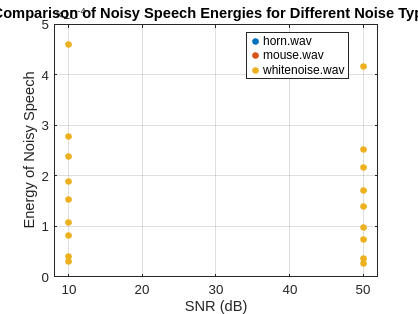


% Save the table as a CSV file for analysis
writetable(resultsTable, 'quantization_results.csv');

% Plot comparison of clean and noisy speech energies
figure;
gscatter(resultsTable.SNR, resultsTable.EnergyNoisySpeech, resultsTable.NoiseType);
xlabel('SNR (dB)');
ylabel('Energy of Noisy Speech');
title('Comparison of Noisy Speech Energies for Different Noise Types');
grid on;


% Observations and Explanation
fprintf('Observations:\n');

Observations:


fprintf('1. Energy of noisy speech is higher for lower SNR values (e.g., 10 dB).\n');

1. Energy of noisy speech is higher for lower SNR values (e.g., 10 dB).


fprintf('2. White noise generally results in higher noisy speech energy due to its broad frequency content.\n');

2. White noise generally results in higher noisy speech energy due to its broad frequency content.


fprintf('3. At higher SNRs (e.g., 50 dB), the energy of noisy speech approaches that of clean speech.\n');

3. At higher SNRs (e.g., 50 dB), the energy of noisy speech approaches that of clean speech.


fprintf('4. Noise types with concentrated spectral content (e.g., horn) affect speech energy differently compared to broadband noise.\n');

4. Noise types with concentrated spectral content (e.g., horn) affect speech energy differently compared to broadband noise.


Question Three

function denoisedSpeech = wienerscalart96_custom(noisySpeech, fs, IS, W, SP)
    % IS: Initial Silence in seconds
    % W: Window Size
    % SP: Overlap Factor
    
    % Ensure default values for parameters
    if nargin < 3, IS = 0.2; end % Initial Silence Default: 0.2s
    if nargin < 4, W = 256; end % Window Size Default: 256 samples
    if nargin < 5, SP = 0.5; end % Overlap Factor Default: 50%
    
    % Convert initial silence to samples
    IS_samples = round(IS * fs);
    
    % Split the noisy signal into overlapping frames
    overlap = round(SP * W);
    step = W - overlap;
    frames = buffer(noisySpeech, W, overlap, 'nodelay');
    
    % Estimate noise power spectrum from initial silence
    noiseFrames = frames(:, 1:ceil(IS_samples / step));
    noisePower = mean(abs(noiseFrames).^2, 2);
    
    % Process each frame using Wiener filtering
    numFrames = size(frames, 2);
    denoisedFrames = zeros(size(frames));
    for i = 1:numFrames
        % Calculate power spectrum of the current frame
        framePower = abs(frames(:, i)).^2;
        
        % Wiener filter gain
        gain = framePower ./ (framePower + noisePower);
        
        % Apply gain to the current frame
        denoisedFrames(:, i) = gain .* frames(:, i);
    end
    
    % Reconstruct the denoised signal from overlapping frames
    denoisedSpeech = overlap_add(denoisedFrames, W, overlap);
end

function signal = overlap_add(frames, W, overlap)
    step = W - overlap;
    signal = zeros((size(frames, 2) - 1) * step + W, 1);
    for i = 1:size(frames, 2)
        startIdx = (i - 1) * step + 1;
        signal(startIdx:startIdx + W - 1) = signal(startIdx:startIdx + W - 1) + frames(:, i);
    end
end


function noisySpeech = add_noise_Three(cleanSpeech, noise, snrTarget)
    % Ensure the noise length matches the clean speech length
    if length(noise) > length(cleanSpeech)
        noise = noise(1:length(cleanSpeech)); % Truncate noise if it's too long
    elseif length(noise) < length(cleanSpeech)
        noise = [noise; zeros(length(cleanSpeech) - length(noise), 1)]; % Pad noise with zeros if it's too short
    end

    % Calculate signal power
    signalPower = mean(cleanSpeech.^2);
    
    % Scale noise to achieve target SNR
    noisePower = mean(noise.^2);
    scale = sqrt(signalPower / (10^(snrTarget / 10) * noisePower));
    scaledNoise = scale * noise;
    
    % Add scaled noise to clean speech
    noisySpeech = cleanSpeech + scaledNoise;
end


% Parameters
cleanSpeechFiles = ["1.wav", "2.wav", "3.wav", ...
                    "4.wav", "5.wav", "6.wav", ...
                    "7.wav", "8.wav", "9.wav", "10.wav"];
noiseTypes = ["horn.wav", "mouse.wav", "whitenoise.wav"];
SNRs = [10, 50]; % Signal-to-Noise Ratios
results = [];

% Process each combination
for i = 1:length(cleanSpeechFiles)
    [cleanSpeech, fs] = audioread(cleanSpeechFiles(i)); % Load clean speech
    cleanSpeech = cleanSpeech(:, 1); % Ensure mono
    for j = 1:length(noiseTypes)
        [noise, fs_noise] = audioread(noiseTypes(j)); % Load noise
        noise = noise(:, 1); % Ensure mono
        if fs ~= fs_noise
            noise = resample(noise, fs, fs_noise); % Resample noise if needed
        end
        for k = 1:length(SNRs)
            % Add noise to clean speech at the given SNR
            noisySpeech = add_noise_Three(cleanSpeech, noise, SNRs(k));

            % Apply Wiener Filter with Default Parameters
            denoisedSpeechDefault = wienerscalart96_custom(noisySpeech, fs);

            % Apply Wiener Filter with Modified Parameters
            IS = 0.2; % Initial Silence (in seconds)
            W = 256; % Window Size
            SP = 0.5; % Overlap Factor
            denoisedSpeechModified = wienerscalart96_custom(noisySpeech, fs, IS, W, SP);

            % Calculate Quantified Values
            energyNoisy = sum(noisySpeech.^2) / length(noisySpeech);
            energyDenoisedDefault = sum(denoisedSpeechDefault.^2) / length(denoisedSpeechDefault);
            energyDenoisedModified = sum(denoisedSpeechModified.^2) / length(denoisedSpeechModified);

            % Store results
            results = [results; {cleanSpeechFiles(i), noiseTypes(j), SNRs(k), ...
                                 energyNoisy, energyDenoisedDefault, energyDenoisedModified}];
        end
    end
end

% Convert results to a table
resultsTable = cell2table(results, 'VariableNames', ...
    {'CleanSpeechFile', 'NoiseType', 'SNR', 'EnergyNoisySpeech', ...
     'EnergyDenoisedDefault', 'EnergyDenoisedModified'});

% Display the table
disp(resultsTable);

    CleanSpeechFile       NoiseType        SNR    EnergyNoisySpeech    EnergyDenoisedDefault    EnergyDenoisedModified
    _______________    ________________    ___    _________________    _____________________    ______________________

       "1.wav"         "horn.wav"          10        4.0698e-05             9.9451e-05                9.9451e-05      
       "1.wav"         "horn.wav"          50           3.7e-05             0.00014761                0.00014761      
       "1.wav"         "mouse.wav"         10        4.0633e-05             0.00016216                0.00016216      
       "1.wav"         "mouse.wav"         50        3.6999e-05             0.00014766                0.00014766      
       "1.wav"         "whitenoise.wav"    10        4.0711e-05             0.000

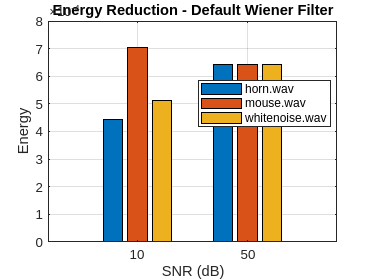


% Save the table for comparison
writetable(resultsTable, 'wiener_filter_results.csv');

% Extract unique SNR values and noise types
uniqueSNRs = unique(resultsTable.SNR);
uniqueNoiseTypes = unique(resultsTable.NoiseType);

% Initialize matrices to store energies
defaultEnergy = zeros(length(uniqueSNRs), length(uniqueNoiseTypes));
modifiedEnergy = zeros(length(uniqueSNRs), length(uniqueNoiseTypes));

% Populate matrices for each combination of SNR and NoiseType
for i = 1:length(uniqueSNRs)
    for j = 1:length(uniqueNoiseTypes)
        % Find rows corresponding to current SNR and NoiseType
        idx = (resultsTable.SNR == uniqueSNRs(i)) & ...
              strcmp(resultsTable.NoiseType, uniqueNoiseTypes{j});
        
        % Handle multiple rows by taking the mean value
        if any(idx)
            defaultEnergy(i, j) = mean(resultsTable.EnergyDenoisedDefault(idx));
            modifiedEnergy(i, j) = mean(resultsTable.EnergyDenoisedModified(idx));
        end
    end
end


% Create grouped bar chart for Default Energy
figure;
bar(categorical(uniqueSNRs), defaultEnergy, 'grouped');
legend(uniqueNoiseTypes, 'Location', 'best');
xlabel('SNR (dB)');
ylabel('Energy');
title('Energy Reduction - Default Wiener Filter');
grid on;

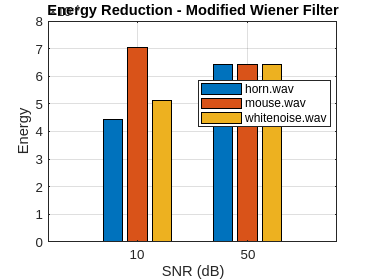


% Create grouped bar chart for Modified Energy
figure;
bar(categorical(uniqueSNRs), modifiedEnergy, 'grouped');
legend(uniqueNoiseTypes, 'Location', 'best');
xlabel('SNR (dB)');
ylabel('Energy');
title('Energy Reduction - Modified Wiener Filter');
grid on;

Question Four

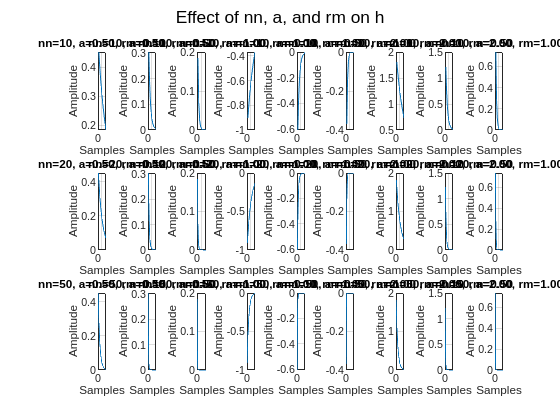

function h = generate_h(nn, a, rm)
    % Example: Generate impulse response with decay and scaling
    h = zeros(1, nn);
    for i = 1:nn
        h(i) = a * exp(-rm * i);
    end
end


% Define the range of parameters
nn_values = [10, 20, 50]; % Example values for nn
a_values = [0.5, -1, 2];  % Example values for a
rm_values = [0.1, 0.5, 1]; % Example values for rm

% Initialize figure for plots
figure;
counter = 1;

% Loop through combinations of nn, a, and rm
for nn = nn_values
    for a = a_values
        for rm = rm_values
            % Generate h based on the parameters
            % Replace `generate_h` with the actual function or logic for h
            h = generate_h(nn, a, rm); 

            % Plot h
            subplot(length(nn_values), length(a_values) * length(rm_values), counter);
            plot(h);
            title(sprintf('nn=%d, a=%.2f, rm=%.2f', nn, a, rm));
            xlabel('Samples');
            ylabel('Amplitude');
            grid on;
            
            % Increment subplot counter
            counter = counter + 1;
        end
    end
end

sgtitle('Effect of nn, a, and rm on h');

Question Five

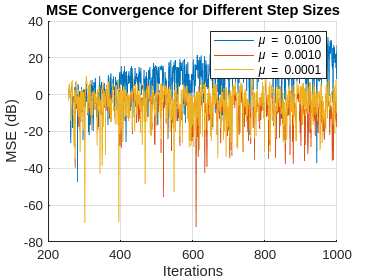

function [error, h_estimated] = lms(input, desired, N, w0, mu, num_iterations)
    % Initialize variables
    h = w0; % Initial filter coefficients
    error = zeros(num_iterations, 1); % Error vector
    h_estimated = zeros(N, 1); % Final impulse response
    
    % LMS iterations
    for n = N:num_iterations
        % Extract input vector
        x = input(n:-1:n-N+1);
        
        % Compute output and error
        y = h' * x;
        e = desired(n) - y;
        error(n) = e;
        
        % Update filter coefficients
        h = h + mu * e * x;
    end
    
    % Store final impulse response
    h_estimated = h;
end


% Parameters
N = 256; % Length of the filter
mu_values = [0.01, 0.001, 0.0001]; % Different step sizes (large, medium, small)
num_iterations = 1000; % Number of iterations for LMS
w0 = zeros(N, 1); % Initial filter coefficients
input = randn(10000, 1); % Random input signal
desired = filter([1, -0.5], 1, input); % Desired signal

% Initialize storage for results
MSE_results = zeros(num_iterations, length(mu_values));
h_results = cell(1, length(mu_values));

% Loop over different values of mu
for i = 1:length(mu_values)
    mu = mu_values(i); % Current step size
    
    % Call LMS function
    [error, h_estimated] = lms(input, desired, N, w0, mu, num_iterations);
    
    % Store MSE and final h
    MSE_results(:, i) = error.^2; % MSE over iterations
    h_results{i} = h_estimated;  % Final impulse response
end

% Plot MSE convergence
figure;
hold on;
for i = 1:length(mu_values)
    plot(10*log10(MSE_results(:, i)), 'DisplayName', sprintf('\\mu = %.4f', mu_values(i)));
end
hold off;
grid on;
xlabel('Iterations');
ylabel('MSE (dB)');
title('MSE Convergence for Different Step Sizes');
legend show;

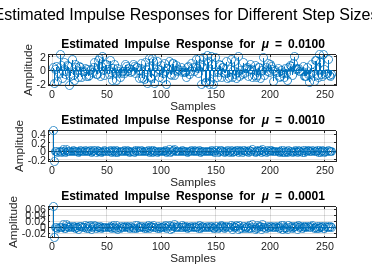


% Plot final impulse response estimates
figure;
for i = 1:length(mu_values)
    subplot(length(mu_values), 1, i);
    stem(h_results{i});
    title(sprintf('Estimated Impulse Response for \\mu = %.4f', mu_values(i)));
    xlabel('Samples');
    ylabel('Amplitude');
    grid on;
end
sgtitle('Estimated Impulse Responses for Different Step Sizes');

**Effect of Large ****μ**:

- Faster updates but can cause oscillations or divergence if too large.

- In extreme cases, μ>1/power of input signal\mu > 1/\text{power of input signal}μ>1/power of input signal leads to instability.

**Effect of Small ****μ**:

- Updates are slow, requiring more iterations for convergence.

- May not fully converge within a limited number of iterations.

**Optimal ****μ**:

- A moderate value balances convergence speed and stability.

- Choose μ\muμ based on the signal characteristics and desired performance.

Question Six

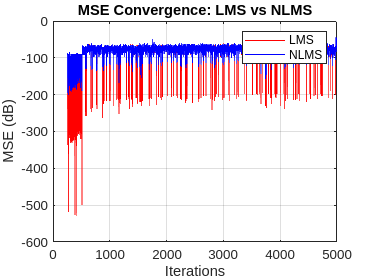

function [error, h_estimated] = nlms(input, desired, N, w0, mu, alpha, num_iterations)
    % Ensure input is a column vector
    input = input(:);
    desired = desired(:);

    % Initialize variables
    h = w0; % Initial filter coefficients
    error = zeros(num_iterations, 1); % Error vector
    
    % NLMS iterations
    for n = N:num_iterations
        % Extract input vector of length N
        x = input(n:-1:n-N+1); % Ensure x has exactly N elements
        
        % Ensure x is a column vector
        x = x(:);

        % Compute filter output and error
        y = h' * x; % Dot product of filter coefficients and input
        e = desired(n) - y;
        error(n) = e;
        
        % Update filter coefficients (normalized)
        normalization = alpha + x' * x; % Avoid division by zero
        h = h + (mu / normalization) * e * x; % NLMS update rule
    end
    
    % Store final impulse response
    h_estimated = h;
end


function [error, h_estimated] = lms_Six(input, desired, N, w0, mu, num_iterations)
    % Ensure input is a column vector
    input = input(:);
    desired = desired(:);

    % Initialize variables
    h = w0; % Initial filter coefficients
    error = zeros(num_iterations, 1); % Error vector
    
    % LMS iterations
    for n = N:num_iterations
        % Extract input vector of length N
        x = input(n:-1:n-N+1); % Ensure x has exactly N elements
        
        % Compute filter output and error
        y = h' * x; % Dot product of filter coefficients and input
        e = desired(n) - y;
        error(n) = e;
        
        % Update filter coefficients
        h = h + mu * e * x; % LMS update rule
    end
    
    % Store final impulse response
    h_estimated = h;
end


% Parameters
N = 256; % Filter length
mu = 0.001; % LMS step size
alpha = 1e-8; % Regularization for NLMS
num_iterations = 5000; % Number of iterations
[input, fs] = audioread('1.wav'); % Input is a speech signal
desired = filter([1, -0.5], 1, input); % Desired output

% Call LMS
[error_lms, h_lms] = lms_Six(input, desired, N, zeros(N, 1), mu, num_iterations);

% Call NLMS
[error_nlms, h_nlms] = nlms(input, desired, N, zeros(N, 1), mu, alpha, num_iterations);

% Plot MSE convergence
figure;
plot(10*log10(error_lms.^2), 'r', 'DisplayName', 'LMS');
hold on;
plot(10*log10(error_nlms.^2), 'b', 'DisplayName', 'NLMS');
hold off;
xlabel('Iterations');
ylabel('MSE (dB)');

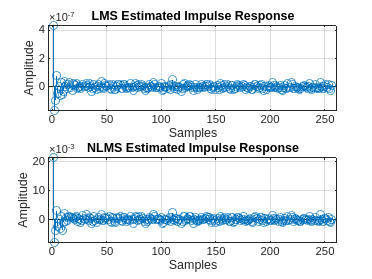

title('MSE Convergence: LMS vs NLMS');
legend show;
grid on;

% Plot estimated impulse responses
figure;
subplot(2, 1, 1);
stem(h_lms);
title('LMS Estimated Impulse Response');
xlabel('Samples');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
stem(h_nlms);
title('NLMS Estimated Impulse Response');

xlabel('Samples');
ylabel('Amplitude');
grid on;
